## Space Vehicle Design Script

Load configurations and combine the structs for the SV

% Initialize the model structure
clc; clear all;
% Load config struct for the Bus
bus = config_bus();
iso = config_Iso_Obench();
payload  = config_Payload();
% Combine the structures
SV = fem.merge_fem_models(bus, iso, payload);

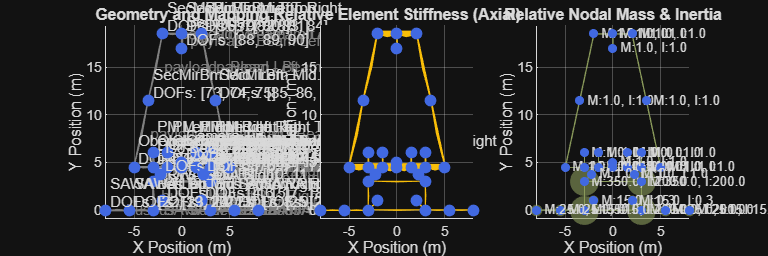

% Visualize the combined spacecraft FEM model
fem.plot_fem_model(SV);

Visualize the SV modes

% fem.plot_mode_shapes(SV,[SV.fn(30),SV.fn(41)])

Simulate disturbances from the RWAs

% Load options profile
% Compute the spacecraft response under reaction-wheel disturbances
options_rwa_disturbances = options_rwa_dist_1hr();
[X_rms_rwa_dist, X_rwa_dist] = fem.calculate_rms(SV, options_rwa_disturbances);

Plot the response of the system to the disturbance

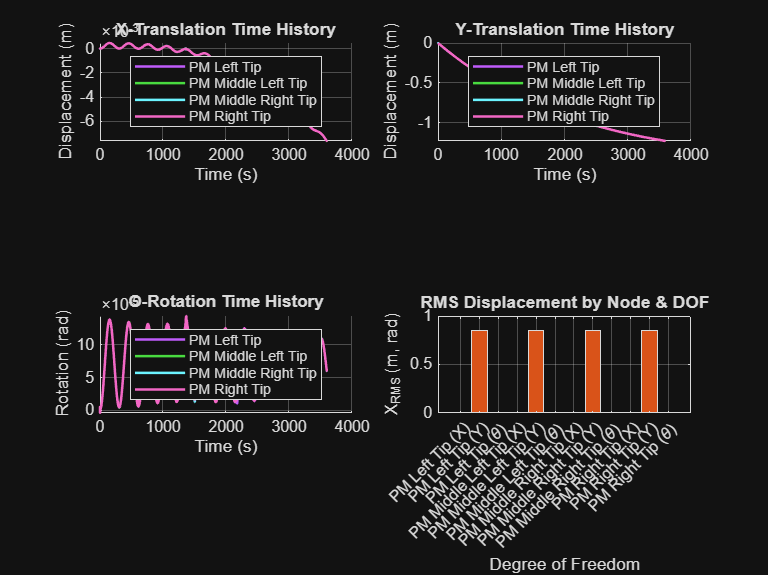

% Start with the response of the primary mirrors
options_plot_ids_PM = {"PM Left Tip", "PM Middle Left Tip", "PM Middle Right Tip", "PM Right Tip"};
fem.plot_rms(SV,options_rwa_disturbances,X_rwa_dist,X_rms_rwa_dist,options_plot_ids_PM);

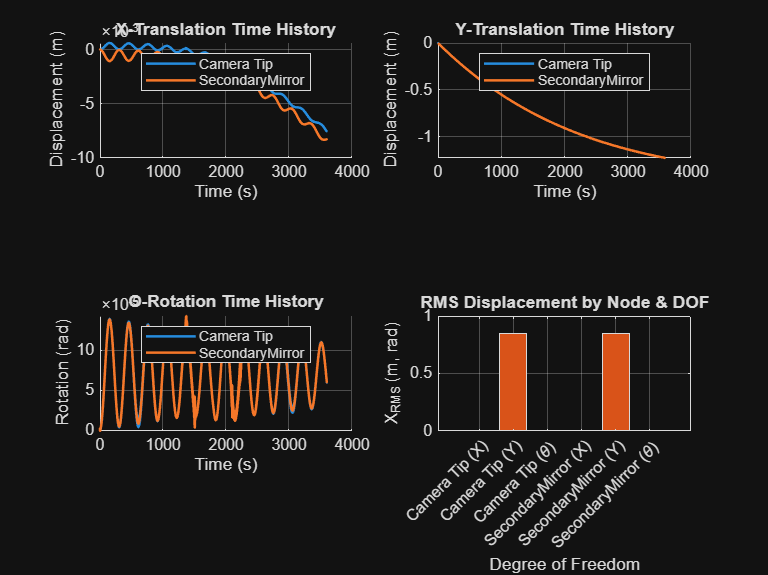

% Next evaluate the response of the secondary mirror and camera
options_plot_ids_SM_Cam = {"SecondaryMirror", "Camera Tip"};
fem.plot_rms(SV,options_rwa_disturbances,X_rwa_dist,X_rms_rwa_dist,options_plot_ids_SM_Cam);

Calculate pointing error of the mirrors

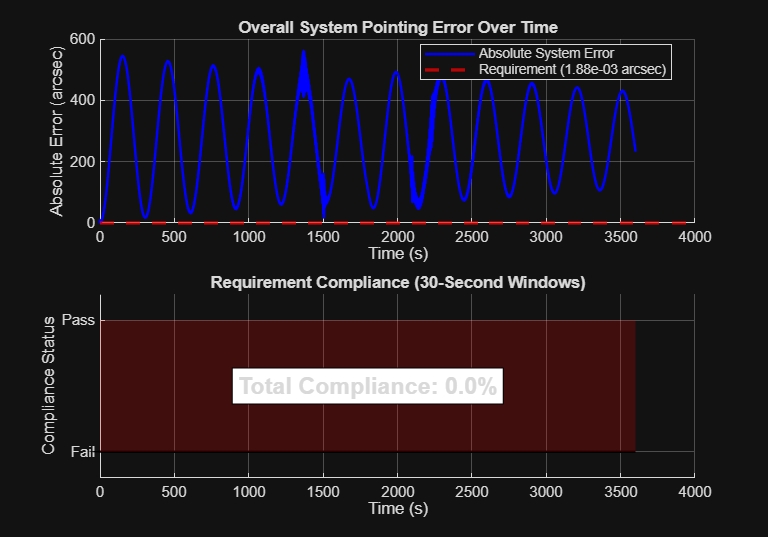

% Establish optical nodes
optical_nodes.sm_id = "SecondaryMirror";
optical_nodes.pm_ids = {"PM Left Tip", "PM Middle Left Tip", "PM Middle Right Tip", "PM Right Tip"};
[pointing_error, components] = fem.calculate_optical_pointing_error(SV, X_rwa_dist, optical_nodes);
threshold = 1.88e-3; window_size = 30;
fem.plot_pointing_error_requirement(options_rwa_disturbances.t, pointing_error, threshold, window_size)

Secondary Mirror Disturbance Analysis: Build State Space

% Define damping and motor disturbance
zeta = 0.01;
options_sm_motor = options_sm_motor();
% Call helper function to generate SS matrecies
[A, B, C, D] = fem.build_state_space(SV, options_sm_motor, optical_nodes, zeta);

Compute PSD Response of the System

% Define range of frequencies
f_range = linspace(10, 100, 1000)';
rms_error = fem.compute_psd_rms(A, B, C, D, f_range);